# Assignment1_Transfer Learning for Image Classification

In this assignment, you will use transfer learning to classify images into 1 of 5 different food categories:

이 과제에서는 전이 학습을 사용하여 이미지를 5가지 음식 카테고리 중 하나로 분류합니다.

- Pizza

- Hot Dog

- Ice Cream

- French Fries

- Chocolate Cake

## 1. Create an image datastore

Create an image datastore which references the folder of the image files. DO NOT use `montage `function to view all images because it takes too much time.

% 이미지 데이터 저장소 만들기
imageDS = imageDatastore("Images/","IncludeSubfolders",true,"LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1001084.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1007122.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1007412.jpg'
                               ... and 4997 more
                              }
                     Folders: {
                              '/Users/jeongseong-yun/Documents/MATLAB/인공지능/Assignment1/Images'
                              }
                      Labels: [chocolate_cake; chocolate_cake; chocolate_cake ... and 4997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"

% DO NOT use montage -> use imtile
% montage 사용하지 않고 imtile 사용
% imageAll = imtile(imageDS)
% imshow(imageAll)

## 2. View an image in image datastore and its size

2-1. Read the first image in the image datastore and display the image.

2-2. Check the size of the first image. What size does the image have?

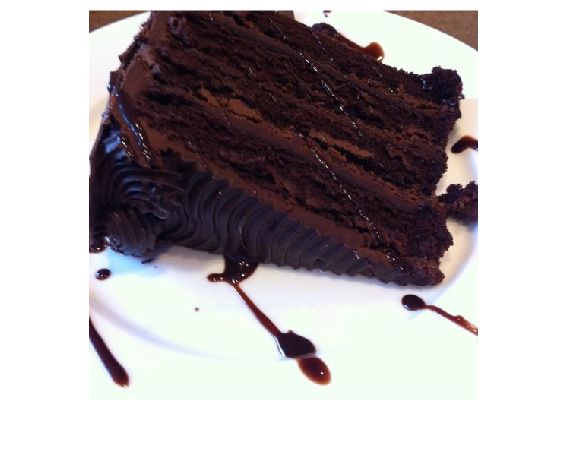

% 2.1 이미지 데이터 저장소에서 첫 번째 이미지 가져오기. 보여주기
imageDS_first = readimage(imageDS, 1);
imshow(imageDS_first)


% 2.2 가져온 첫번째 이미지의 크기를 확인하기. 
firstImage_size = size(imageDS_first)

firstImage_size =    512   512     3


## 3. Split Image datastore and resize images for AlexNet

3-1. Split dataset into 2 set: train and test.

3-2. Resize the images in the image datastore to 227 by 227 for AlexNet.

% 3-1 훈련데이터와 테스트데이터 두개의 섹션으로 나누기
imageDS = imageDatastore("Images/","IncludeSubfolders",true,"LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1001084.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1007122.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1007412.jpg'
                               ... and 4997 more
                              }
                     Folders: {
                              '/Users/jeongseong-yun/Documents/MATLAB/인공지능/Assignment1/Images'
                              }
                      Labels: [chocolate_cake; chocolate_cake; chocolate_cake ... and 4997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"

[train, test] = splitEachLabel(imageDS, 0.8) % train 데이터를 0.8, test 데이터를 0.2로 나누기

train =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1001084.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1007122.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/1007412.jpg'
                               ... and 3997 more
                              }
                     Folders: {
                              '/Users/jeongseong-yun/Documents/MATLAB/인공지능/Assignment1/Images'
                              }
                      Labels: [chocolate_cake; chocolate_cake; chocolate_cake ... and 3997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
 

test =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/381453.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/3815047.jpg';
                              ' .../MATLAB/인공지능/Assignment1/Images/chocolate_cake/3816656.jpg'
                               ... and 997 more
                              }
                     Folders: {
                              '/Users/jeongseong-yun/Documents/MATLAB/인공지능/Assignment1/Images'
                              }
                      Labels: [chocolate_cake; chocolate_cake; chocolate_cake ... and 997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
     

% 3-2 이미지 저장소를 알렉스넷을 사용하기 위해 크기 바꾸기
aug_imageDS = augmentedImageDatastore([227,227], imageDS)

aug_imageDS =   augmentedImageDatastore - 속성 있음:

             NumObservations: 5000
                       Files: {5000×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


train_Data = augmentedImageDatastore([227,227], train)

train_Data =   augmentedImageDatastore - 속성 있음:

             NumObservations: 4000
                       Files: {4000×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


test_Data = augmentedImageDatastore([227,227], test)

test_Data =   augmentedImageDatastore - 속성 있음:

             NumObservations: 1000
                       Files: {1000×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## 4. Modify AlexNet

4-1. Import AlexNet

4-2. Modify appropriate layers so that the modified network correctly works for your datasets

% 4-1 알렉스넷 import >> 애드온 탐색기 추가, mat 파일 등 
% 1. 사전 훈련된 컨볼루젼 신경망 알렉스넷 사용
net = alexnet

net =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layers = net.Layers

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU                  ReLU
     4   'norm1'    교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU                  ReLU
     8   'norm2'    교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU                  ReLU
    12   'conv4'    2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13 

layers_input = layers(1)

layers_input =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


layers_output = layers(end)

layers_output =   ClassificationOutputLayer - 속성 있음:

            Name: 'output'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   하이퍼파라미터
    LossFunction: 'crossentropyex'


classes = layers_output.Classes

classes = 1000×1 categorical 배열
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 



% 4-2 사전 훈련된 네트워크 수정. 피자 데이터셋을 적절하게 수정.
% 23번째의 완전연결계층 -> fullyConnectedLayers(1), output -> classificationLayer()
% trainNetwork Invalid training data. The output size (1000) of the last layer does not match the number of classes of the responses (1).
layers(23) = fullyConnectedLayer(5) % 사용자 지정된 작업에 맞게 새로운 레이어로 대체. 응답 클래스 수 1

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU                  ReLU
     4   'norm1'    교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU                  ReLU
     8   'norm2'    교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU                  ReLU
    12   'conv4'    2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13 

layers(end) = classificationLayer() % 사용자 지정 작업을 위한 분류 레이어로 대체

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'    영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU                  ReLU
     4   'norm1'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU                  ReLU
     8   'norm2'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU                  ReLU
    12   'conv4'   2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'   

## 5. Create training options and train the network 훈련 옵션 생성, 네트워크 훈련

5-1. Create the following training options

- Stochastic Gradient Descent with Momentum (SGDM) 확률적 경사하강법

- Initial learning rate: 0.001

- Max Epochs: 10

- Display training-progress during training

5-2. Train the network

% 5-1 훈련 옵션 생성, 확률적 경사하강법(비 = 0.001), Max 에폭 = 10, training-progress
opts = trainingOptions("sgdm", "InitialLearnRate",0.001,"Plots","training-progress","MaxEpochs",10)

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
              

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０８　｜　　　　　　２４．２２％　｜　　　　　３．８６９９　｜　　　０．００１０　｜
｜　　　　　　　２　｜　　　　　　５０　｜　　　　　００：０４：１５　｜　　　　　　８１．２５％　｜　　　　　０．３８５８　｜　　　０．００１０　｜
｜　　　　　　　４　｜　　　　　１００　｜　　　　　００：０８：２２　｜　　　　　　９６．０９％　｜　　　　　０．１４１７　｜　　　０．００１０　｜
｜　　　　　　　５　｜　　　　　１５０　｜　　　　　００：１２：５２　｜　　　　　　９２．１９％　｜　　　　　０．１８２２　｜　　　０．００１０　｜
｜　　　　　　　７　｜　　　　　２００　｜　　　　　００：１７：２３　｜　　　　　　９７．６６％　｜　　　　　０．０９１６　｜　　　０．００１０　｜
｜　　　　　　　９　｜　　　　　２５０　｜　　　　　００：２１：４８　｜　　　　　　９９．２２％　｜　　　　　０．０４２３　｜　　　０．００１０　｜
｜　　　　　　１０　｜　　　　　３００　｜　　　　　００：２６：１１　｜　　　　　１００．００％　｜　　　　　０．０３３６　｜　　　０．００１０　｜
｜　　　　　　１０　｜　　　　　３１０　｜　　　　　００：２７：０４　｜　　　　　　９９．２２％　｜　　　　　０．０１６１　｜　　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝

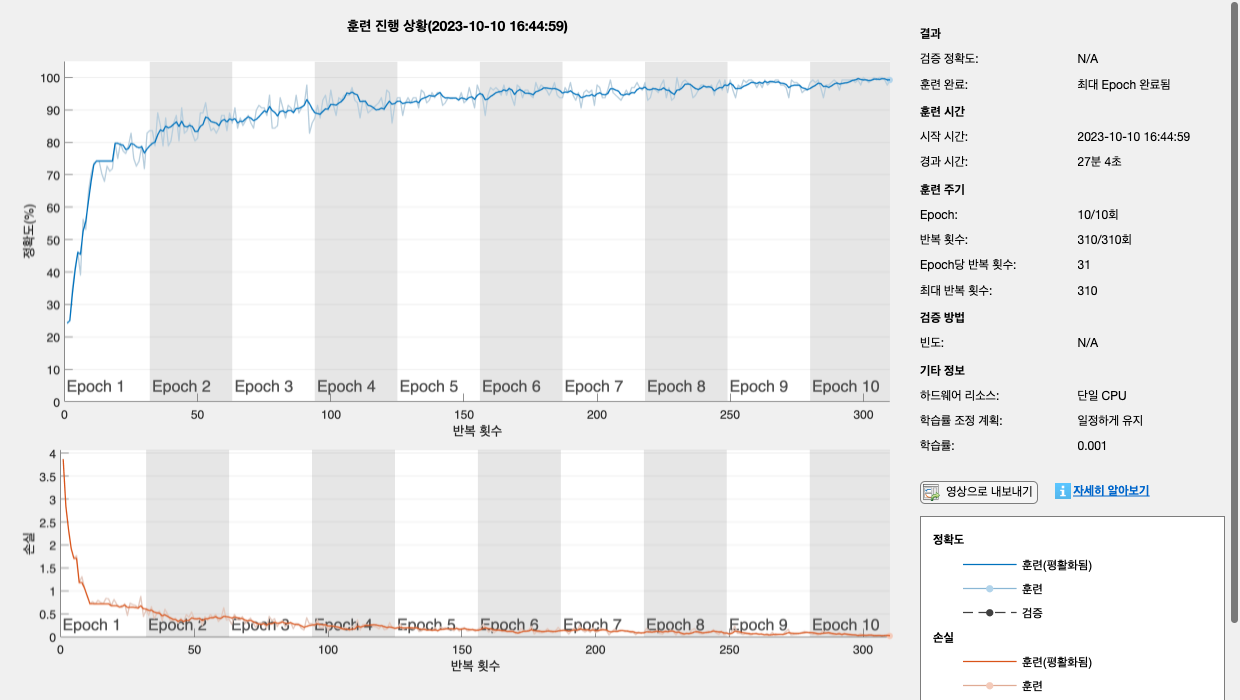

newnet =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}



% 5-2 Train the network
newnet = trainNetwork(train_Data, layers, opts)

## 6. Test the Network

Test the network with the test data

6-1. Classify the test images by the new network

6-2. Calculate the prediction accuracy of the test data

6-3. Display the result with confusion chart

% 6-1 새로운 network 테스트 이미지 분류
test_pred = classify(newnet, test_Data) % test_Data Prediction

test_pred = 1000×1 categorical 배열
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     french_fries 
     chocolate_cake 
     hot_dog 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 


test_GT = test.Labels % Ground truth of the test data 실제 데이터

test_GT = 1000×1 categorical 배열
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 
     chocolate_cake 


% 6-2 테스트 데이터의 정확도 계산
test_Acc = nnz(test_pred == test_GT)/numel(test_GT)

test_Acc = 0.8950

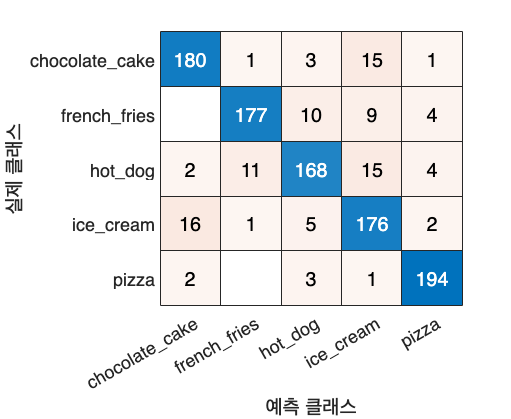

% Display confusion chart
confusionchart(test_GT, test_pred)